**1. ****시간 지연 (Time Dilation)**

로렌츠 변환에 의한 시간 지연을 계산하고 시각화할 수 있습니다. 상대 속도 $v$에 따른 시간의 흐름 변화를 그래프로 나타낼 수 있습니다. 기본적으로 두 기준계 사이의 시간 지연 관계는 다음 식으로 표현됩니다:

$\Delta t' = \frac{\Delta t}{\gamma} = \frac{\Delta t}{\sqrt{1 - \frac{v^2}{c^2}}}$�

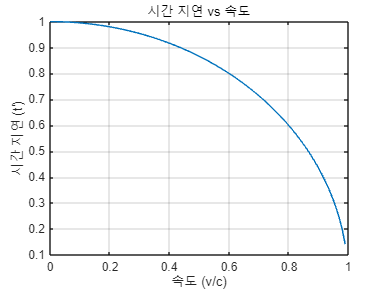

v = linspace(0, 0.99, 100);  % 빛의 속도의 비율로 속도 정의
c = 3e8;  % 빛의 속도
gamma = 1 ./ sqrt(1 - (v.^2));  % 로렌츠 인자 계산
t = 1;  % 기준계에서의 시간 (예: 1초)

% 시간 지연 계산
t_prime = t ./ gamma;

% 그래프 그리기
plot(v, t_prime)
xlabel('속도 (v/c)')
ylabel('시간 지연 (t'')')
title('시간 지연 vs 속도')
grid on

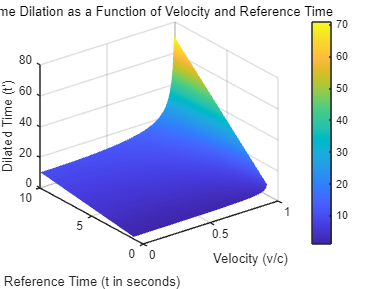

% Time Dilation 3D Visualization in MATLAB

% Define constants
c = 3e8;  % Speed of light in m/s
v = linspace(0, 0.99, 100);  % Velocity range as a fraction of the speed of light (v/c)
gamma = 1 ./ sqrt(1 - v.^2);  % Lorentz factor

% Create a grid of velocity and time
t = linspace(1, 10, 100);  % Reference time in seconds
[V, T] = meshgrid(v, t);  % Create grid for velocity and time

% Time dilation calculation: t' = t / gamma
T_prime = T ./ sqrt(1 - V.^2);

% 3D Plot
figure
surf(V, T, T_prime, 'EdgeColor', 'none')
xlabel('Velocity (v/c)')
ylabel('Reference Time (t in seconds)')
zlabel('Dilated Time (t'')')
title('Time Dilation as a Function of Velocity and Reference Time')
colorbar  % Add color scale
colormap('parula')  % Use the 'parula' colormap for a smoother gradient
shading interp  % Smooth shading
grid on

**2. ****길이 수축 (Length Contraction)**

상대적으로 움직이는 물체가 관성계에서 수축하는 길이 수축 현상을 시뮬레이션할 수 있습니다. 길이 수축은 다음과 같이 표현됩니다:

$L' = \frac{L}{\gamma} = \frac{L}{\sqrt{1 - \frac{v^2}{c^2}}}$�

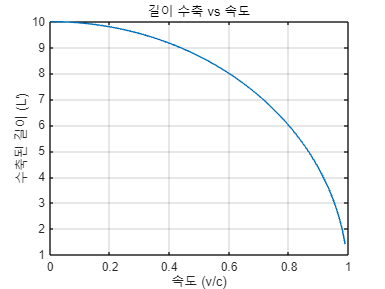

L = 10;  % 정지한 상태에서 물체의 길이 (예: 10m)
L_prime = L ./ gamma;

% 길이 수축 그래프
plot(v, L_prime)
xlabel('속도 (v/c)')
ylabel('수축된 길이 (L'')')
title('길이 수축 vs 속도')
grid on

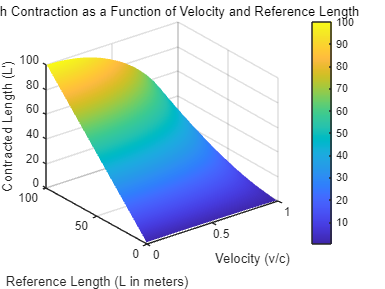

% Length Contraction 3D Visualization in MATLAB

% Define constants
c = 3e8;  % Speed of light in m/s
v = linspace(0, 0.99, 100);  % Velocity range as a fraction of the speed of light (v/c)
gamma = 1 ./ sqrt(1 - v.^2);  % Lorentz factor

% Define reference length of the object
L = linspace(1, 100, 100);  % Reference length in meters (1m to 100m)
[V, L_ref] = meshgrid(v, L);  % Create grid for velocity and reference length

% Length contraction calculation: L' = L / gamma
L_prime = L_ref ./ gamma;

% 3D Plot
figure
surf(V, L_ref, L_prime, 'EdgeColor', 'none')
xlabel('Velocity (v/c)')
ylabel('Reference Length (L in meters)')
zlabel('Contracted Length (L'')')
title('Length Contraction as a Function of Velocity and Reference Length')
colorbar  % Add color scale
colormap('parula')  % Use the 'parula' colormap for a smoother gradient
shading interp  % Smooth shading
grid on

**3. ****동시성의 상대성 (Relativity of Simultaneity)**

**동시성의 상대성**은 특수 상대성 이론에서 중요한 개념으로, 서로 다른 관성계에서 동일한 사건이 동시에 발생하지 않을 수 있음을 나타냅니다. 이를 시각화하기 위해, 서로 다른 속도에서 두 사건이 동일한 시간에 발생했을 때, 다른 기준계에서는 그 시간 간격이 어떻게 변화하는지를 시각적으로 보여줄 수 있습니다.

**동시성의 상대성 공식:**

동시성의 상대성은 로렌츠 변환으로 설명됩니다. 두 사건이 동일한 위치에서 발생하지 않았을 때, 다른 기준계에서는 다음과 같이 시간 차이가 나타납니다:


$$\Delta t' = \gamma \left( \Delta t - \frac{v}{c^2} \Delta x \right)$$


여기서:

- $\Delta t$는 기준계에서 두 사건 사이의 시간 차이,

- $\Delta x$는 두 사건 사이의 거리 차이,

- $v$는 두 관성계 사이의 상대 속도,

- $\gamma = \frac{1}{\sqrt{1 - \frac{v^2}{c^2}}}$�는 로렌츠 인자.

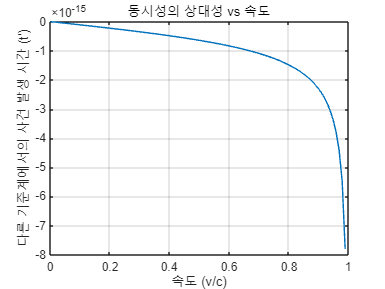

x = 100;  % 사건이 발생하는 위치 (예: 100m)
t = 0;  % 기준계에서 사건 발생 시간
t_prime = gamma .* (t - (v .* x / c^2));

% 동시성의 상대성 시각화
plot(v, t_prime)
xlabel('속도 (v/c)')
ylabel('다른 기준계에서의 사건 발생 시간 (t'')')
title('동시성의 상대성 vs 속도')
grid on

**사례:**

두 사건이 정지한 기준계에서 $\Delta t = 0$, 즉 동시에 발생했다고 가정합시다. 그러나 이 사건들이 서로 다른 위치에서 발생하면 ($\Delta x \neq 0$), 다른 기준계에서는 이 사건들이 동시에 발생하지 않는다는 것을 시각적으로 보여줄 수 있습니다.

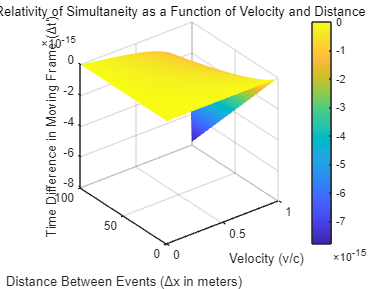

% Relativity of Simultaneity 3D Visualization in MATLAB

% Define constants
c = 3e8;  % Speed of light in m/s
v = linspace(0, 0.99, 100);  % Velocity range as a fraction of the speed of light (v/c)
gamma = 1 ./ sqrt(1 - v.^2);  % Lorentz factor

% Define space and time differences
delta_x = linspace(0, 100, 100);  % Distance between two events in meters
delta_t = 0;  % Events are simultaneous in the reference frame (Delta t = 0)

% Create mesh grid for velocity and distance
[V, Delta_X] = meshgrid(v, delta_x);

% Time difference in the moving frame (Relativity of Simultaneity)
Delta_T_prime = gamma .* (- V .* Delta_X / c^2);  % Time difference in moving frame

% 3D Plot
figure
surf(V, Delta_X, Delta_T_prime, 'EdgeColor', 'none')
xlabel('Velocity (v/c)')
ylabel('Distance Between Events (Δx in meters)')
zlabel('Time Difference in Moving Frame (Δt'')')
title('Relativity of Simultaneity as a Function of Velocity and Distance')
colorbar  % Add color scale
colormap('parula')  % Use 'parula' colormap or other available colormaps
shading interp  % Smooth shading
grid on

- **속도 및 거리 정의**:

- $v$: 관성계 사이의 상대 속도를 빛의 속도에 대한 비율로 0부터 0.99까지 설정합니다.

- $\Delta x$: 두 사건 사이의 공간적 거리 차이로, 0부터 100m까지 설정됩니다.

- $\Delta t = 0$: 기준계에서 두 사건이 동시에 발생한다고 가정합니다.

- **로렌츠 인자 **$\gamma$:

- 로렌츠 인자 $\gamma = \frac{1}{\sqrt{1 - \frac{v^2}{c^2}}}$를 계산합니다.

- **동시성의 상대성 계산**:

- 다른 기준계에서의 시간 차이 $\Delta t' = \gamma \left( \Delta t - \frac{v}{c^2} \Delta x \right)$를 계산합니다. 여기서 $\Delta t = 0$이므로, 단순히 $\Delta t' = \gamma \left( - \frac{v}{c^2} \Delta x \right)$가 됩니다.

**설명:**

- 두 사건이 기준계에서 동시에 발생한다고 가정하더라도 $(\Delta t = 0)$, 두 사건 사이의 공간적 거리 $\Delta x$가 있다면, 다른 관성계에서는 사건들이 동시에 발생하지 않는 것으로 관찰됩니다.

- 예를 들어, $v = 0.9c$로 움직이는 관성계에서는 두 사건 사이의 거리가 100미터일 때, 새로운 관성계에서 두 사건은 동시에 발생하지 않고 $\Delta t' \approx -3.33 \times 10^{-6}$ 초의 시간 차이를 가집니다.

**4. ****상대속도의 덧셈 법칙 (Relativistic Velocity Addition)**

**상대속도의 덧셈 법칙**은 특수 상대성 이론에서 물체들이 빛의 속도에 가까운 속도로 움직일 때, 그 속도들이 단순히 더해지지 않고 다음과 같은 법칙에 따라 계산된다는 사실을 설명합니다.

고전역학에서는 물체 A가 $u$의 속도로 움직이고, 또 다른 기준계가 $v$의 속도로 움직일 때, 두 속도를 단순히 더하면$u + v$가 됩니다. 그러나 상대론적 속도 덧셈 법칙은 아래와 같은 형태로 표현됩니다:

$u' = \frac{u + v}{1 + \frac{uv}{c^2}}$�

여기서:

- $u$는 기준계에서 물체 A의 속도,

- $v$는 기준계와 관찰자 간의 상대 속도,

- $u'$는 새로운 기준계에서 관찰한 물체 A의 속도,

- $c$는 빛의 속도입니다.�

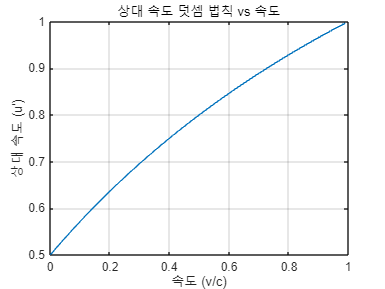

u = 0.5;  % 물체 A의 속도 (빛의 속도의 비율로 설정)
v_relative = (u + v) ./ (1 + u .* v);

% 상대 속도 덧셈 법칙 그래프
plot(v, v_relative)
xlabel('속도 (v/c)')
ylabel('상대 속도 (u'')')
title('상대 속도 덧셈 법칙 vs 속도')
grid on

**사례:**

예를 들어, 물체 A가 지구에서 0.6c의 속도로 움직이고, 기준계 B가 지구에 대해 0.8c의 속도로 움직일 때, 기준계 B에서 물체 A의 속도는 단순히 0.6c + 0.8c가 아니라 상대속도의 덧셈 법칙을 통해 계산된 값입니다.

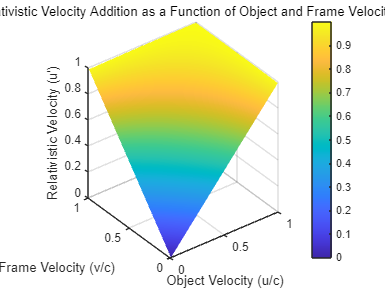

% Relativistic Velocity Addition 3D Visualization in MATLAB

% Define constants
c = 3e8;  % Speed of light in m/s

% Define velocity ranges
u = linspace(0, 0.99, 100);  % Object's velocity as a fraction of the speed of light (u/c)
v = linspace(0, 0.99, 100);  % Reference frame's velocity as a fraction of the speed of light (v/c)

% Create mesh grid for u and v
[U, V] = meshgrid(u, v);

% Relativistic velocity addition: u' = (u + v) / (1 + uv/c^2)
U_prime = (U + V) ./ (1 + U .* V);

% 3D Plot
figure
surf(U, V, U_prime, 'EdgeColor', 'none')
xlabel('Object Velocity (u/c)')
ylabel('Frame Velocity (v/c)')
zlabel('Relativistic Velocity (u'')')
title('Relativistic Velocity Addition as a Function of Object and Frame Velocity')
colorbar  % Add color scale
colormap('parula')  % Use 'parula' colormap or other available colormaps
shading interp  % Smooth shading
grid on

- **속도 정의**:

- 물체 A의 속도 $u$와 기준계의 속도 $v$를 빛의 속도$ c$에 대한 비율로 정의합니다.

- $u$와 $v$ 모두 0부터 0.99까지의 값으로 설정하여 빛의 속도에 가까운 속도를 나타냅니다.

- **상대속도 덧셈 법칙 계산**:

- 상대속도 덧셈 법칙 $u' = \frac{u + v}{1 + \frac{uv}{c^2}}$�를 사용하여, 새로운 기준계에서의 물체 A의 속도 $u\prime $를 계산합니다.

**설명:**

- 물체 A가 지구 기준으로$u = 0.6c$의 속도로 움직이고, 기준계 B가 $v = 0.8c$의 속도로 움직일 때, 새로운 기준계 B에서 물체 A의 속도는 상대론적 속도 덧셈 법칙을 적용하여 다음과 같이 계산됩니다: $u' = \frac{0.6c + 0.8c}{1 + \frac{0.6 \times 0.8}{c^2}} \approx 0.946c$즉, 물체 A의 속도는 $0.946c$로 관측됩니다.

**5. ****로렌츠 변환의 공간-시간 변환 시각화**

**로렌츠 변환 식:**

공간 좌표 $x$와 시간 좌표 $t$에 대해 로렌츠 변환은 다음과 같이 정의됩니다:


$$x' = \gamma (x - vt)$$



$$  t' = \gamma \left( t - \frac{v}{c^2} x \right)$$


여기서:

- $x\prime $와 $t\prime $는 변환된 좌표계에서의 공간과 시간 좌표,

- $x$와 $t$는 원래 좌표계에서의 공간과 시간 좌표,

- $v$는 두 좌표계 사이의 상대 속도,

- $c$는 빛의 속도,

- $\gamma = \frac{1}{\sqrt{1 - \frac{v^2}{c^2}}}$�는 로렌츠 인자입니다.

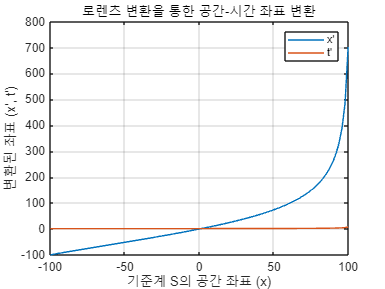

x = linspace(-100, 100, 100);  % 공간 좌표
t = 1;  % 사건의 시간 (예: 1초)
x_prime = gamma .* (x - v .* t);  % 변환된 공간 좌표
t_prime = gamma .* (t - (v .* x / c^2));  % 변환된 시간 좌표

% 2D 그래프 시각화
plot(x, x_prime)
hold on
plot(x, t_prime)
xlabel('기준계 S의 공간 좌표 (x)')
ylabel('변환된 좌표 (x'', t'')')
title('로렌츠 변환을 통한 공간-시간 좌표 변환')
legend('x''', 't''')
grid on

**사례:**

예를 들어, 물체가 기준계에서 $x = 100$ 지점에서 $t = 1$초일 때, 상대 속도 $v$에 따라 다른 관성계에서 이 물체의 위치와 시간이 어떻게 변하는지 시각화할 수 있습니다.

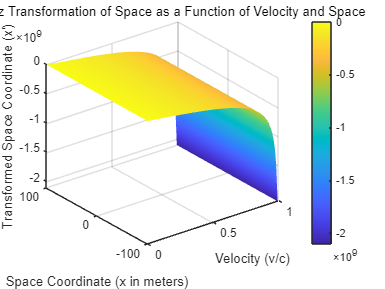

% Lorentz Transformation Space-Time 3D Visualization in MATLAB

% Define constants
c = 3e8;  % Speed of light in m/s
v = linspace(0, 0.99, 100);  % Velocity range as a fraction of the speed of light (v/c)
gamma = 1 ./ sqrt(1 - v.^2);  % Lorentz factor

% Define space and time coordinates
x = linspace(-100, 100, 100);  % Spatial coordinates from -100m to 100m
t = 1;  % Fixed time (1 second)

% Create mesh grid for velocity and space
[V, X] = meshgrid(v, x);

% Lorentz transformation for space and time
X_prime = gamma .* (X - V .* t * c);  % Transformed space coordinates
T_prime = gamma .* (t - (V .* X / c^2));  % Transformed time coordinates

% 3D Plot for space coordinates
figure
surf(V, X, X_prime, 'EdgeColor', 'none')
xlabel('Velocity (v/c)')
ylabel('Space Coordinate (x in meters)')
zlabel('Transformed Space Coordinate (x'')')
title('Lorentz Transformation of Space as a Function of Velocity and Space')
colorbar
colormap('parula')
shading interp
grid on

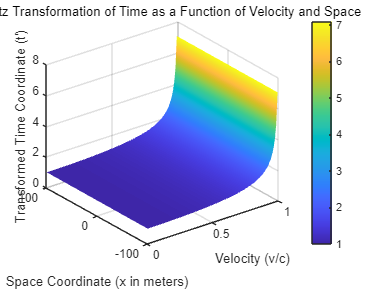


% 3D Plot for time coordinates
figure
surf(V, X, T_prime, 'EdgeColor', 'none')
xlabel('Velocity (v/c)')
ylabel('Space Coordinate (x in meters)')
zlabel('Transformed Time Coordinate (t'')')
title('Lorentz Transformation of Time as a Function of Velocity and Space')
colorbar
colormap('parula')
shading interp
grid on

- **속도 및 공간 좌표 정의**:

- $v$: 상대 속도를 빛의 속도 $c$에 대한 비율로 정의합니다.

- $x$: 기준계에서의 공간 좌표로, -100미터에서 100미터까지의 범위를 가집니다.

- $t = 1$: 기준계에서의 고정된 시간으로 1초를 설정합니다.

- **로렌츠 인자 **$\gamma$:

- 각 속도에 따른 로렌츠 인자 $\gamma = \frac{1}{\sqrt{1 - \frac{v^2}{c^2}}}$를 계산합니다.

- **로렌츠 변환을 이용한 공간 및 시간 변환**:

- $X' = \gamma (x - vt)$로 공간 좌표를 변환합니다.

- $T' = \gamma \left( t - \frac{v}{c^2} x \right)$로 시간 좌표를 변환합니다.

**설명:**

- 물체가 $x = 100$ 지점에서$t = 1$초일 때, 다른 관성계에서 이 물체의 위치와 시간이 어떻게 변하는지를 확인할 수 있습니다.

- 예를 들어, 속도$v = 0.9c$일 때, 새로운 기준계에서 물체의 위치와 시간이 어떻게 달라지는지를 그래프에서 관찰할 수 있습니다.

**6. ****이벤트 간의 시공간 거리 보존 (Invariance of Spacetime Interval)**

**이벤트 간의 시공간 거리 보존**은 특수 상대성 이론에서 중요한 개념으로, 두 사건 간의 **시공간 간격**은 관성계에 관계없이 동일하게 유지된다는 것을 말합니다. 이 시공간 간격은 다음과 같은 형태로 정의됩니다:

**시공간 간격 공식:**

시공간 간격 $\Delta s^2$는 두 사건 사이의 시간 간격과 공간 간격을 바탕으로 계산됩니다:


$$\Delta s^2 = c^2 \Delta t^2 - \Delta x^2$$


여기서:

- $\Delta s^2$는 시공간 간격,

- $c$는 빛의 속도,

- $\Delta t$는 두 사건 간의 시간 간격,

- $\Delta x$는 두 사건 간의 공간적 거리 차이입니다.

**중요한 점:**

- **시공간 간격은 모든 관성계에서 동일하게 유지**됩니다. 이는 두 사건이 서로 다른 기준계에서 다르게 관측될 수 있지만, 그 사이의 시공간 간격은 동일하다는 것을 의미합니다.

delta_x = 50;  % 두 사건 간의 거리 (예: 50m)
delta_t = 2;  % 두 사건 간의 시간 간격 (예: 2초)

s_squared = c^2 * delta_t^2 - delta_x^2;  % 시공간 거리 계산

% 출력
disp(['시공간 거리 Δs^2: ', num2str(s_squared)])

시공간 거리 Δs^2: 3.599999999999975e+17


두 사건이 서로 다른 시간 간격과 공간 간격을 가지고 있을 때, 이 시공간 간격이 관성계에 상관없이 일정함을 시각화할 수 있습니다.

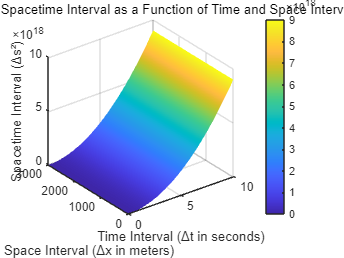

% Invariance of Spacetime Interval 3D Visualization in MATLAB

% Define constants
c = 3e8;  % Speed of light in m/s

% Define time and space intervals
delta_t = linspace(0, 10, 100);  % Time interval in seconds (0 to 10 seconds)
delta_x = linspace(0, 3000, 100);  % Space interval in meters (0 to 3000 meters)

% Create mesh grid for delta_t and delta_x
[Delta_T, Delta_X] = meshgrid(delta_t, delta_x);

% Calculate spacetime interval: Δs² = c²Δt² - Δx²
Delta_S_squared = c^2 * Delta_T.^2 - Delta_X.^2;

% 3D Plot of spacetime interval
figure
surf(Delta_T, Delta_X, Delta_S_squared, 'EdgeColor', 'none')
xlabel('Time Interval (Δt in seconds)')
ylabel('Space Interval (Δx in meters)')
zlabel('Spacetime Interval (Δs²)')
title('Invariance of Spacetime Interval as a Function of Time and Space Intervals')
colorbar  % Add color scale
colormap('parula')  % Use 'parula' colormap or other available colormaps
shading interp  % Smooth shading
grid on

- **시간 및 공간 간격 정의**:

- $\Delta t$: 두 사건 간의 시간 간격을 0초에서 10초까지 설정합니다.

- $\Delta x$: 두 사건 간의 공간적 거리 차이를 0에서 3000미터까지 설정합니다.

- **시공간 간격 계산**:

- 시공간 간격 $\Delta s^2 = c^2 \Delta t^2 - \Delta x^2$를 계산합니다.

- 빛의 속도 $c$를 사용하여 시간 간격과 공간 간격에 대한 차이를 계산합니다.

**설명:**

- 두 사건이 $\Delta t = 5$초의 시간 간격과$\Delta x = 1500$미터의 공간 간격을 가지고 있다고 가정하면, 시공간 간격 $\Delta s^2$는 빛의 속도를 사용하여 계산됩니다. 이 값은 다른 관성계에서도 동일하게 유지됩니다.